# Example 2.9: Failure of Control System for Reactor

Note: this script reproduces Example 2.9 (Section 2.1.5) of **Statistics for Chemical Engineers**: number of monthly failures of a control system, modeled as a Poisson RV. Victor Z UW-Madison, 2020 example Poisson RV

clc; clear all; close all hidden;

rng(0);       % for reproducibility      

## Failure data

generate random failure sequences

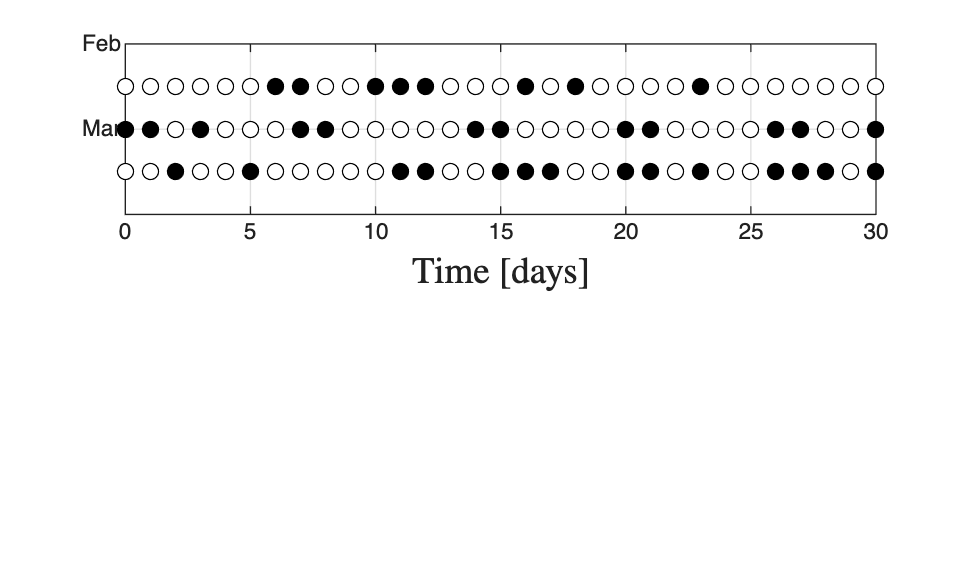

z = 30;       % days
lambda = 10;  % average occurrences per z
t = 0:1:z;    % time vector
n=length(t);  % number of times
N=3;          % number of samples

for k=1:N

m(k) = poissrnd(lambda); % number of occurrences

y = zeros(1,n);
y(1:m(k)) = 1;
y = y(randperm(n));

subplot(2,1,1)
for j=1:length(y)
if y(j)==1 %failure
    scatter(t(j),k,'blacko','MarkerFaceColor','black','MarkerEdgeColor','black') 
    hold on
else %normal
    scatter(t(j),k,'blacko','MarkerFaceColor','w','MarkerEdgeColor','black')
    hold on
end
end
grid on
axis([min(t) max(t) 0 4])
set(gca,'yticklabels',{'','Mar','Feb','Jan',''})
xlabel('$\textrm{Time [days]}$','interpreter','Latex','Fontsize',14)
box on
end

print -depsc ch2_poissprocess.eps

## Poisson model

compute pdf for poisson

lambdahat=mean(m);

## Probabilities

compute probabilities

p=poisspdf(0,lambdahat)

p = 1.1967e-05


p=poisspdf(30,lambdahat)

p = 1.9278e-06


p=poisspdf(11,lambdahat)

p = 0.1188

## Note

As in the book, the probability of 11 failures in a month is 0.12; the pdf is evaluated at integers only (11, not 11.3), because the domain contains integers.